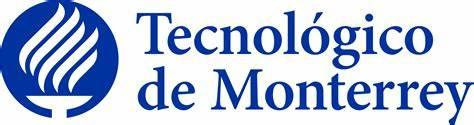

**Evaluación 1**

**Fundamentación de robótica gpo101**

**Hecho por:**

A01736196 | Abraham Ortiz Castro

 ITESM puebla

**Profesor:**

Alfredo García Suárez.

*2 de febrero del 2024.*

# Primer ejercicio.

## Ejercicio seleccionado.

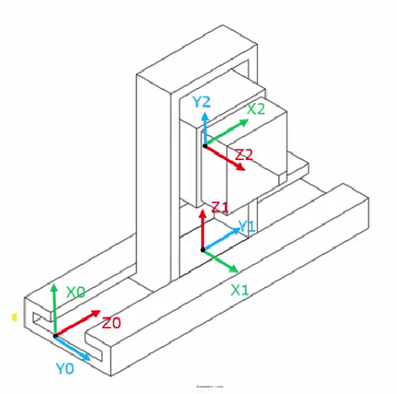

## Ejes seleccionados.

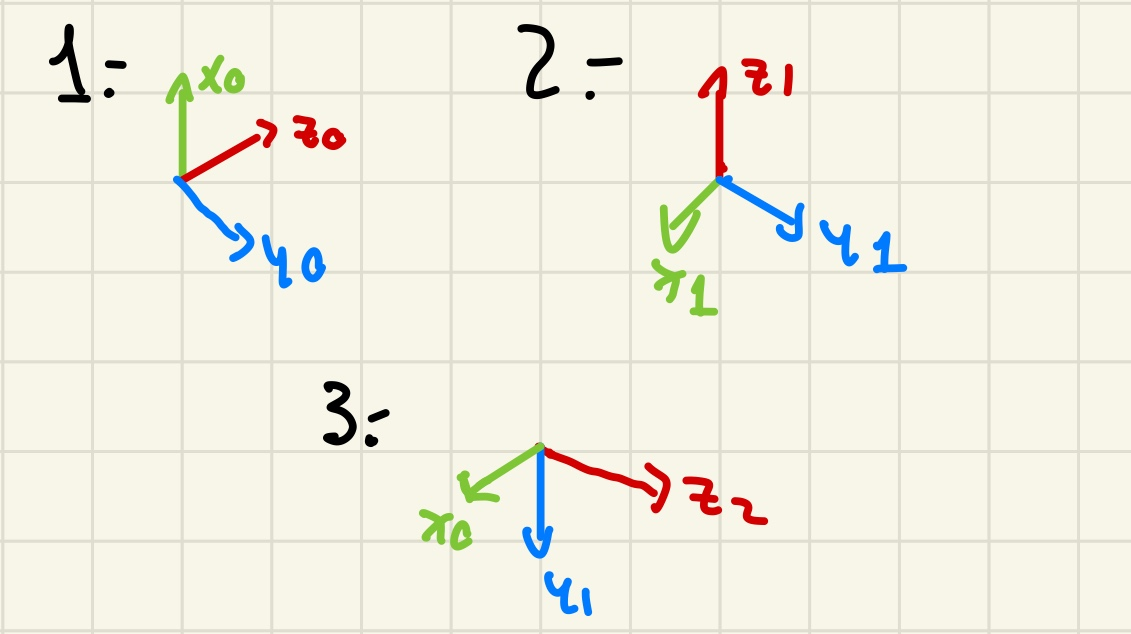

En los ejes seleccionados se puede observar la lógica que se tuvo para resolver este ejercicio. 

Antes que nada me gustaría decir que según el análisis no existirán movimientos angulares en el sistema, solamente lineales, por lo tanto solamente existirá una variación en el tiempo de ln.

Para empezar se tomó el eje uno, esto debido a que el eje z ya se encontraba alineado con el movimiento de la primera articulación, en este caso la translación se encuentra en z por lo tanto se pone l1 en z a la translación y en los otros ejes cero debido a que no existe movimiento, hablando de la rotación lo que se necesita es rotar 90 grados sobre el eje y (de z a  x) para que la z quede alineada con  el movimiento de la segunda articulación (segundo sistema).

Para el segundo análisis, el recorrido de la misma manera es en z, debido a que se ha rotado el eje de referencia (usando el 2), por lo tanto se le pone l2 en z a la translación y los otros dos ejes no tienen movimiento, hablando de la rotación se necesita rotar -90 grados sobre el eje x (de z a y)para  que z quede alineada con el movimiento de la tercera arituclación (tercer sistema).

En el tercer análisis el movimiento se encuentra de la misma manera en z, esto debido al otro cambio del sistema de referencia,  por lo tanto se le pone l3 en z a la translación y los otros dos ejes quedan sin movimiento. Hablando de la rotación, ya no se necesita, por lo tanto se le pone la matriz identidad.

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms l1(t) l2(t) l3(t) t 

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[1 1 1];

%Creamos el vector de coordenadas articulares
Q= [l1, l2, l3];
%disp('Coordenadas generalizadas');
%pretty (Q);

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0 ; 0; l1];
%Matriz de rotación de la junta 1 respecto a 0.... -90º y1 
R(:,:,1)= [ 0  0  1 ;
            0  1  0;
           -1  0  0];
%Posición de la articulación 1 respecto a 0
P(:,:,2)= [0 ; 0; l2];
%Matriz de rotación de la junta 1 respecto a 0.... -90º y1 
R(:,:,2)= [ 1  0  0 ;
            0  0  1;
            0  -1  0];

P(:,:,3)= [0 ; 0; l3];
%Matriz de rotación de la junta 1 respecto a 0.... -90º y1 
R(:,:,3)= [1  0  0 ;
           0  1  0;
           0  0  1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 
%Inicializamos las INVERSAS de las matrices de rotación vistas desde el marco de referencia inercial
RO_inv(:,:,GDL)= R(:,:,GDL); 

for i = 1:GDL
    i_str= num2str(i);
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    RO_inv(:,:,i)= transpose(RO(:,:,i));
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(RO_inv(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1


/  0, 0, 1,   0   \
|                 |
|  0, 1, 0,   0   |
|                 |
| -1, 0, 0, l1(t) |
|                 |
\  0, 0, 0,   1   /



Matriz de Transformación global T1


/  0, 0, 1,   0   \
|                 |
|  0, 1, 0,   0   |
|                 |
| -1, 0, 0, l1(t) |
|                 |
\  0, 0, 0,   1   /



Matriz de Transformación local A2


/ 1,  0, 0,   0   \
|                 |
| 0,  0, 1,   0   |
|                 |
| 0, -1, 0, l2(t) |
|                 |
\ 0,  0, 0,   1   /



Matriz de Transformación global T2


/  0, -1, 0, l2(t) \
|                  |
|  0,  0, 1,   0   |
|                  |
| -1,  0, 0, l1(t) |
|                  |
\  0,  0, 0,   1   /



Matriz de Transformación local A3


/ 1, 0, 0,   0   \
|                |
| 0, 1, 0,   0   |
|                |
| 0, 0, 1, l3(t) |
|                |
\ 0, 0, 0,   1   /



Matriz de Transformación global T3


/  0, -1, 0, l2(t) \
|                  |
|  0,  0, 1, l3(t) |
|                  |
| -1,  0, 0, l1(t) |
|                  |
\  0,  0, 0,   1   /




%Calculamos la matriz de transformación del marco de referencia inercial
%visto desde el actuador final
% disp(strcat('Matriz de Transformación T', GDL_str,'_O calculada de forma manual'));
% RF_O=RO_inv(:,:,GDL);
% PF_O=-RF_O*PO(:,:,GDL);
% TF_O= simplify([RF_O PF_O; Vector_Zeros 1]);
% pretty(TF_O);   

%disp(strcat('Matriz de Transformación T', GDL_str,'_O calculada de forma auntomática'));
%pretty(simplify(inv(T(:,:,GDL))));
%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ 0, 1, 0 \
|         |
| 0, 0, 1 |
|         |
\ 1, 0, 0 /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0, 0 \
|         |
| 0, 0, 0 |
|         |
\ 0, 0, 0 /





disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/ ________ \
|  d       |
| -- l2(t) |
| dt       |
|          |
| ________ |
|  d       |
| -- l3(t) |
| dt       |
|          |
| ________ |
|  d       |
| -- l1(t) |
\ dt       /



disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/ 0 \
|   |
| 0 |
|   |
\ 0 /



Los resulatdos tienen mucho sentido, en primera, no existirá velocidad angular en ningún eje en ningún momento, debido a que siempre se van a estar transladando ya que todas las articulaciones son prismáticas. Hablando del resultado de la velocidad angular de la misma manera se puede observar un movimiento esperado, ya que si vemos las velocidad respecto al mundo (el primer sistema de referencia puesto arriba), el movimiento de l2 queda solamente sobre el eje x, l3 queda solamente en el movimiento de y, y l1 queda solamente en el movimiento de z. Por lo tanto sí se ha expresado correctamente el comportamiento del sistema.

# Segundo ejercicio.

## Ejercicio seleccionado.

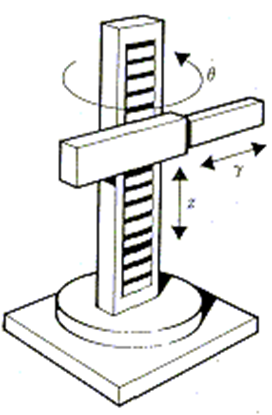

## Sistema de referencia.

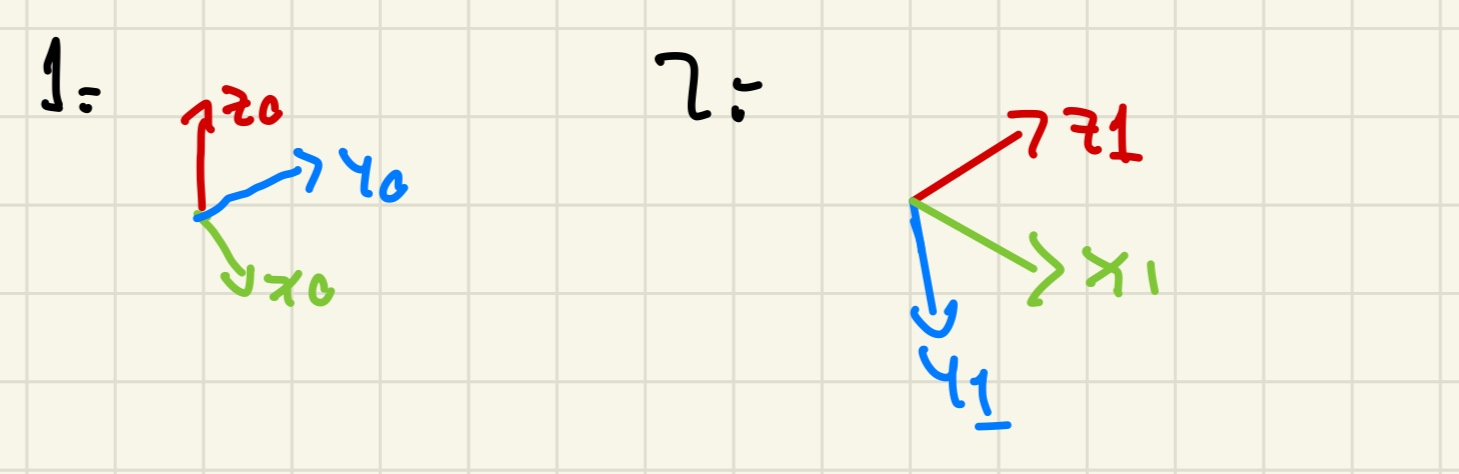

En este ejercicio solamente fueron necesarios dos sistemas de referencia, a continuación se explica como se realizó el análisis.

Se empezó tomando el sistema de referencia 1, ya que de esa manera el sistema va a rotar sobre el eje z haciendo todo más fácil,  para la translación solamenrt tome en cuenta lo que puede medir esa articulación, por ello fue que le puse l1 (es constante) en z , y para la rotación puse que esta va a depender de th1 respecto al tiempo del eje de rotacion en z. En este caso no necesite mover el sistema de referencia debido a que queda alineado con la segunda articulación.

Para la segunda ariticulación, esta ya es prismática, por lo tanto para la translación se tomo en cuenta l2 respecto al tiempo, y ya que se tomo el sistema de referencia 1, este movimiento solamente será en el eje z, poniendo l2 en z y cero en z y y. En este caso la rotación si es necesaria,  ya que para que z quede respecto a la tercer articulación se requiere rotar -90 grados sobre el eje x (de z a y), poniendo asi el eje z alineado.

Para la tercera articulación, ya tomando en cuenta el sistema 2, para la translación solamente existirá el movimiento de l3 sobre el eje z, por lo tanto en z se le pondrá l3 y en los otros dos ejes o para la translación. Ya no se necesita ninguna rotación, por lo tanto solamente se pone la matriz identidad para respetar la actual.

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms l1 l2(t) l3(t) t th1(t) 

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 1 1];

%Creamos el vector de coordenadas articulares
Q= [th1, l2, l3];
%disp('Coordenadas generalizadas');
%pretty (Q);

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0 ; 0; l1];
%Matriz de rotación de la junta 1 respecto a 0.... -90º y1 
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];
%Posición de la articulación 1 respecto a 0
P(:,:,2)= [0 ; 0; l2];
%Matriz de rotación de la junta 1 respecto a 0.... -90º y1 
R(:,:,2)= [1  0   0;
           0  0   1;
           0  -1  0];

P(:,:,3)= [0 ; 0; l3];
%Matriz de rotación de la junta 1 respecto a
R(:,:,3)= [1  0  0 ;
           0  1  0;
           0  0  1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 
%Inicializamos las INVERSAS de las matrices de rotación vistas desde el marco de referencia inercial
RO_inv(:,:,GDL)= R(:,:,GDL); 

for i = 1:GDL
    i_str= num2str(i);
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    RO_inv(:,:,i)= transpose(RO(:,:,i));
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(RO_inv(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1


/ cos(th1(t)), -sin(th1(t)), 0,  0 \
|                                  |
| sin(th1(t)),  cos(th1(t)), 0,  0 |
|                                  |
|      0,            0,      1, l1 |
|                                  |
\      0,            0,      0,  1 /



Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0,  0 \
|                                  |
| sin(th1(t)),  cos(th1(t)), 0,  0 |
|                                  |
|      0,            0,      1, l1 |
|                                  |
\      0,            0,      0,  1 /



Matriz de Transformación local A2


/ 1,  0, 0,   0   \
|                 |
| 0,  0, 1,   0   |
|                 |
| 0, -1, 0, l2(t) |
|                 |
\ 0,  0, 0,   1   /



Matriz de Transformación global T2


/ cos(th1(t)),  0, -sin(th1(t)),      0     \
|                                           |
| sin(th1(t)),  0,  cos(th1(t)),      0     |
|                                           |
|      0,      -1,       0,      l1 + l2(t) |
|                                           |
\      0,       0,       0,           1     /



Matriz de Transformación local A3


/ 1, 0, 0,   0   \
|                |
| 0, 1, 0,   0   |
|                |
| 0, 0, 1, l3(t) |
|                |
\ 0, 0, 0,   1   /



Matriz de Transformación global T3


/ cos(th1(t)),  0, -sin(th1(t)), -sin(th1(t)) l3(t) \
|                                                   |
| sin(th1(t)),  0,  cos(th1(t)),  cos(th1(t)) l3(t) |
|                                                   |
|      0,      -1,       0,          l1 + l2(t)     |
|                                                   |
\      0,       0,       0,               1         /




%Calculamos la matriz de transformación del marco de referencia inercial
%visto desde el actuador final
% disp(strcat('Matriz de Transformación T', GDL_str,'_O calculada de forma manual'));
% RF_O=RO_inv(:,:,GDL);
% PF_O=-RF_O*PO(:,:,GDL);
% TF_O= simplify([RF_O PF_O; Vector_Zeros 1]);
% pretty(TF_O);   

%disp(strcat('Matriz de Transformación T', GDL_str,'_O calculada de forma auntomática'));
%pretty(simplify(inv(T(:,:,GDL))));
%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ -cos(th1(t)) l3(t), 0, -sin(th1(t)) \
|                                     |
| -sin(th1(t)) l3(t), 0,  cos(th1(t)) |
|                                     |
\          0,         1,       0      /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0, 0 \
|         |
| 0, 0, 0 |
|         |
\ 1, 0, 0 /





disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/   ________               _________                   \
|    d                      d                          |
| - -- l3(t) sin(th1(t)) - -- th1(t) cos(th1(t)) l3(t) |
|   dt                     dt                          |
|                                                      |
|  ________               _________                    |
|   d                      d                           |
|  -- l3(t) cos(th1(t)) - -- th1(t) sin(th1(t)) l3(t)  |
|  dt                     dt                           |
|                                                      |
|                       ________                       |
|                        d                             |
|                       -- l2(t)                       |
\                       dt                             /



disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/     0     \
|           |
|     0     |
|           |
| _________ |
|  d        |
| -- th1(t) |
\ dt        /



Los resultados tienen mucho sentido, empezando que según el sistema del mundo (el primer sistema de este ejercicio) solamente existirá rotación en el eje z y este será determinado por el angulo th1, algo que expresa la matriz de velocidad angular, hablando de los otros dos ejes, en ningún momento se espera algun movimiento angular, por lo tanto deben de ser cero.

Hablando de la translación de la misma manera tiene mucho sentido, ya que tomando en cuenta el sistema del mundo, el único movimiento lineal en z será de l2 , porque es la única articulación que se mueve afectando a ese eje, por lo tanto los otros movimientos se encontrarán en x y y. De la misma manera tiene sentido que en las coordenadas de x y y se tengan contemplados solamente l3 y el movimiento del angulo th1, ya que estas son las variables son las únicas que determinarán su posicion de esos dos ejes.